clear s; close all; clc
comPort='COM4'; baudRate=115200;
s=serialport(comPort,baudRate); s.Timeout=5; flush(s);
sc=uint8([3 hex2dec('CC') hex2dec('AA') hex2dec('55')]);
ec=uint8([hex2dec('CC') 3 hex2dec('55') hex2dec('AA')]);
buf=uint8([]); t0=tic; got=false;
while true
    b=read(s,1,"uint8"); if isempty(b), if toc(t0)>30, break; else, continue; end, end
    buf(end+1)=b;
    if ~got
        k=strfind(buf,sc);
        if ~isempty(k), buf=buf(k(1)+numel(sc):end); got=true; else, if numel(buf)>32, buf=buf(end-32+1:end); end; end
    else
        k=strfind(buf,ec);
        if ~isempty(k), payload=buf(1:k(1)-1); break; end
    end
end
clear s;
payload=payload(1:4*floor(numel(payload)/4));
dw=typecast(uint8(payload),'uint32').';
u12=bitand(dw,uint32(4095));
s12=double(u12); s12(s12>2047)=s12(s12>2047)-4096;
fs=15625;
fprintf('mean(code)=%g  min=%g  max=%g\n',mean(s12),min(s12),max(s12));

mean(code)=-2.12983  min=-734  max=618


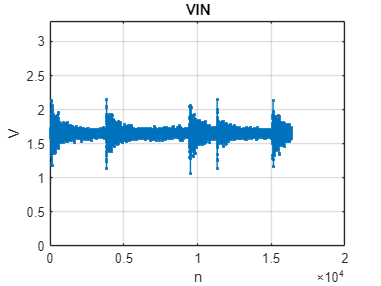

vin=1.65 + s12*(3.3/4096);
figure; plot(vin,'.-'); grid on; title('VIN'); xlabel('n'); ylabel('V'); ylim([0 3.3]);

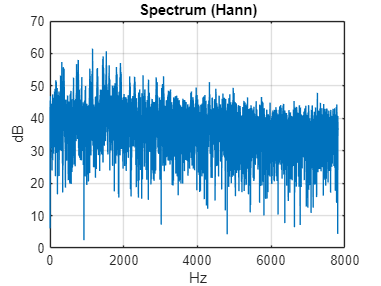


v_zero = (double(u12) - mean(double(u12)))*(3.3/4095);
x = v_zero(:);
w = hann(length(x),'periodic');
X = fft(x.*w);
K = floor(length(X)/2);
f = (0:K-1)*(fs/length(X));
figure; plot(f,20*log10(abs(X(1:K))+1e-12)); grid on; xlabel('Hz'); ylabel('dB'); title('Spectrum (Hann)');

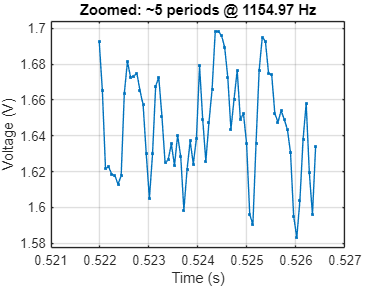


n = numel(vin);
[~,idx1] = max(abs(X(2:K)));
if isempty(idx1) || idx1<=0
    f0 = fs/1000;
else
    f0 = f(idx1+1);
end
ps = max(1, round(fs/max(f0,1e-6)));
periods = 5;
Nzoom = min(n, periods*ps);
startSample = max(1, round(n/2 - Nzoom/2));
endSample = min(startSample + Nzoom - 1, n);

seg = vin(startSample:endSample);
rngV = max(seg)-min(seg)+eps;
yl = [max(0, min(seg)-0.05*rngV), min(3.3, max(seg)+0.05*rngV)];

t = ((startSample-1):(endSample-1))/fs;
figure; plot(t, seg, '.-'); grid on; ylim(yl);
xlabel('Time (s)'); ylabel('Voltage (V)');
title(sprintf('Zoomed: ~%d periods @ %.2f Hz', periods, f0));